# Generate Untargeted and Targeted Adversarial Examples for Image Classification using squeezenet

This example shows how to use the fast gradient sign method (FGSM) and the basic iterative method (BIM) to generate adversarial examples for a pretrained neural network.

Neural networks can be susceptible to a phenomenon known as *adversarial examples* [1], where very small changes to an input can cause the input to be misclassified. These changes are often imperceptible to humans.

In this example, you create two types of adversarial examples: 

- Untargeted — Modify an image so that it is misclassified as any incorrect class.

- Targeted — Modify an image so that it is misclassified as a specific class.

## Load Network and Image

Load a network that has been trained on the ImageNet [2] data set and convert it to a `dlnetwork`.

net = squeezenet;
lgraph = layerGraph(net);
lgraph.Layers(end).Name;
lgraph = removeLayers(lgraph,lgraph.Layers(end).Name);
dlnet = dlnetwork(lgraph);
summary(dlnet);

   Initialized: true

   Number of learnables: 1.2M

   Inputs:
      1   'data'   227×227×3 images



Extract the class labels.

classes = categories(net.Layers(end).Classes)

classes = 1000×1 cell array
    {'tench'                   }
    {'goldfish'                }
    {'great white shark'       }
    {'tiger shark'             }
    {'hammerhead'              }
    {'electric ray'            }
    {'stingray'                }
    {'cock'                    }
    {'hen'                     }
    {'ostrich'                 }
    {'brambling'               }
    {'goldfinch'               }
    {'house finch'             }
    {'junco'                   }
    {'indigo bunting'          }
    {'robin'                   }
    {'bulbul'                  }
    {'jay'                     }
    {'magpie'                  }
    {'chickadee'               }
    {'water ouzel'             }
    {'kite'                    }
    {'bald eagle'              }
    {'vulture'                 }
    {'great grey owl'          }
    {'European fire salamander'}
    {'common newt'             }
    {'eft'                     }
    {'spotted salamander'      }
    {'axolotl' 

Load an image to use to generate an adversarial example. The image is a picture of a tabby.

img = imread("GenerateAdversarialExamplesExample/cat.jpeg");
T = "tabby";

Resize the image to match the input size of the network.

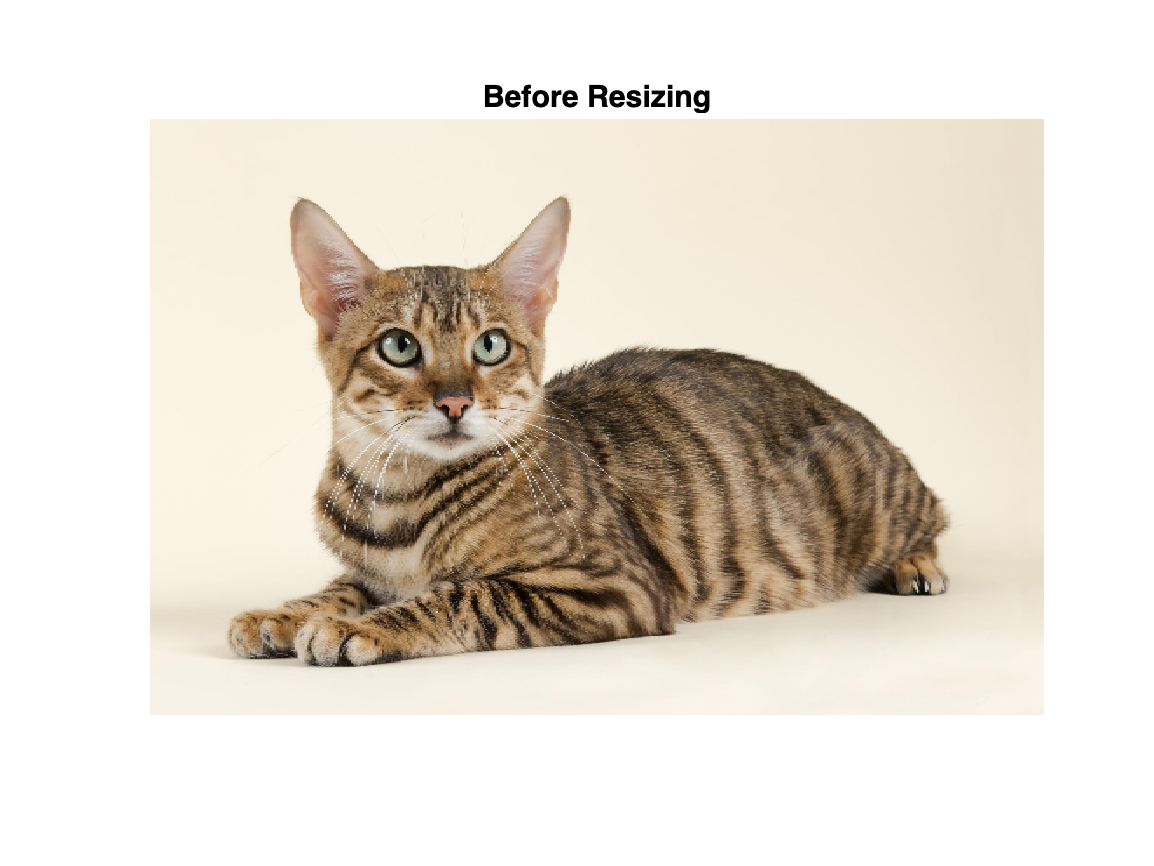

imshow(img)
title("Before Resizing")

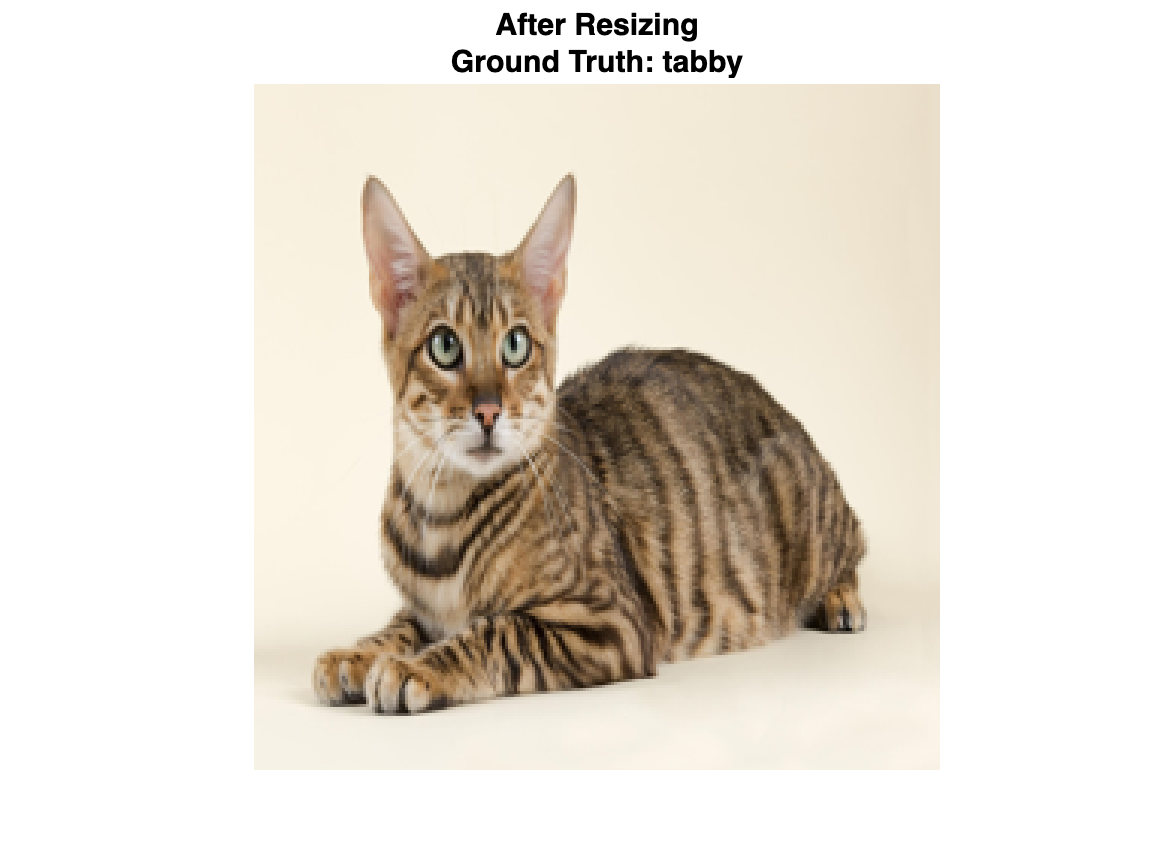

inputSize = dlnet.Layers(1).InputSize;
img = imresize(img,inputSize(1:2));

figure
imshow(img)
title(["After Resizing", "Ground Truth: " + T])

Prepare the image by converting it to a `dlarray`.

X = dlarray(single(img),"SSCB");

Prepare the label by one-hot encoding it.

T = onehotencode(T,1,'ClassNames',classes);
T = dlarray(single(T),"CB");

## Untargeted Fast Gradient Sign Method

Create an adversarial example using the untargeted FGSM [3]. This method calculates the gradient $\nabla_X L\left(X,T\right)$ of the loss function $L$, with respect to the image $X$ you want to find an adversarial example for, and the class label $T$. This gradient describes the direction to "push" the image in to increase the chance it is misclassified. You can then add or subtract a small error from each pixel to increase the likelihood the image is misclassified. 

The adversarial example is calculated as follows:

$X_{\textrm{adv}} =X+\epsilon \ldotp \textrm{sign}\left(\nabla_X L\left(X,T\right)\right)$.

Parameter $\epsilon$ controls the size of the push. A larger $\epsilon$ value increases the chance of generating a misclassified image, but makes the change in the image more visible. This method is untargeted, as the aim is to get the image misclassified, regardless of which class.

Calculate the gradient of the image with respect to the tabby class.

gradient = dlfeval(@untargetedGradients,dlnet,X,T); 

Set `epsilon` and generate the adversarial example.

epsilon = 30;
XAdv = X + epsilon*sign(gradient);

Predict the class of the original image and the adversarial image.

YPred = predict(dlnet,X);
YPred = onehotdecode(squeeze(YPred),classes,1)

YPred = categorical
     tabby 


YPredAdv = predict(dlnet,XAdv);
YPredAdv = onehotdecode(squeeze(YPredAdv),classes,1)

YPredAdv = categorical
     jigsaw puzzle 


Display the original image, the perturbation added to the image, and the adversarial image. If the `epsilon` value is large enough, the adversarial image has a different class label from the original image.

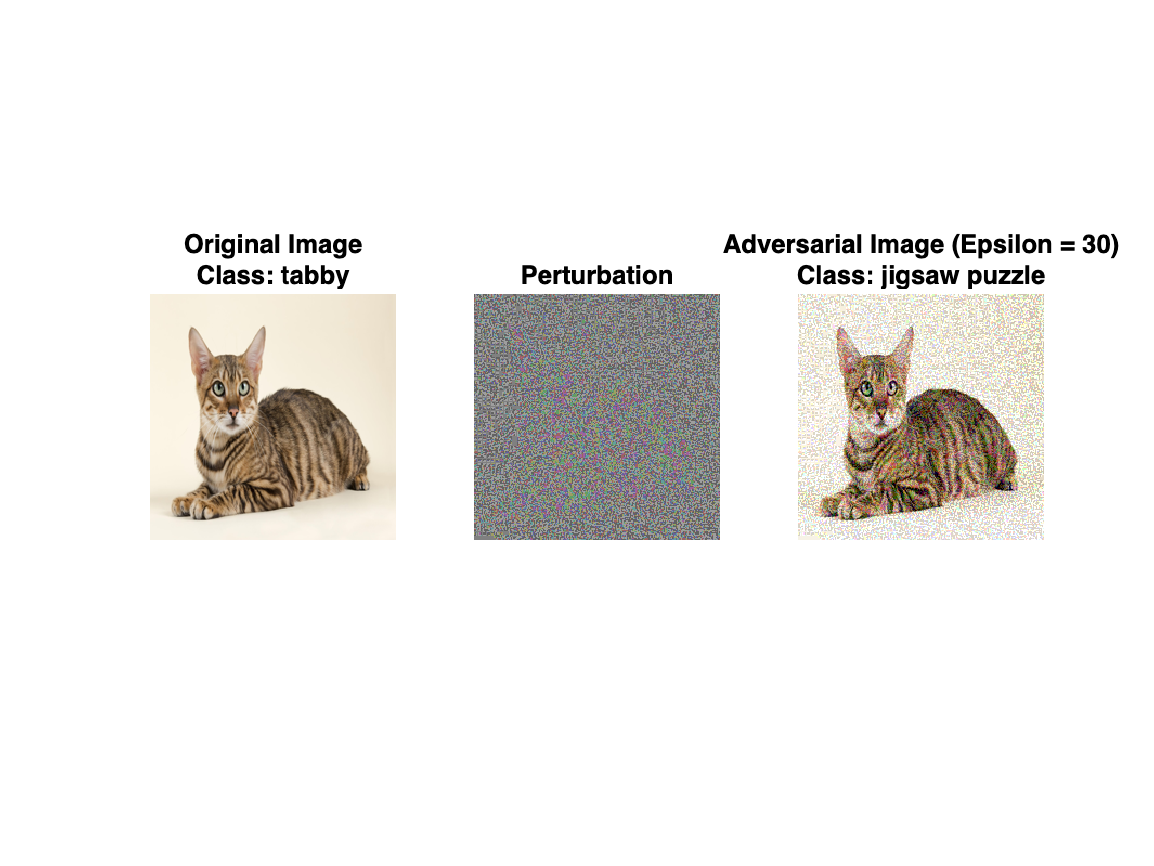

showAdversarialImage(X,YPred,XAdv,YPredAdv,epsilon);

The network correctly classifies the unaltered image as a **tabby**. However, because of perturbation, the network misclassifies the adversarial image as a **jigsaw puzzle**. Once added to the image, the perturbation is imperceptible, demonstrating how adversarial examples can exploit robustness issues within a network.

## Targeted Adversarial Examples

A simple improvement to FGSM is to perform multiple iterations. This approach is known as the basic iterative method (BIM) [4] or projected gradient descent [5]. For the BIM, the size of the perturbation is controlled by parameter $\alpha$ representing the step size in each iteration. This is as the BIM usually takes many, smaller, FGSM steps in the direction of the gradient. After each iteration, clip the perturbation to ensure the magnitude does not exceed $\epsilon$. This method can yield adversarial examples with less distortion than FGSM. 

When you use untargeted FGSM, the predicted label of the adversarial example can be very similar to the label of the original image. For example, a dog might be misclassified as a different kind of dog. However, you can easily modify these methods to misclassify an image as a specific class. Instead of maximizing the cross-entropy loss, you can minimize the mean squared error between the output of the network and the desired target output.

Generate a targeted adversarial example using the BIM and the tiger shark target class.

targetClass = "tiger shark";
targetClass = onehotencode(targetClass,1,'ClassNames',classes);

Increase the `epsilon` value, set the step size `alpha`, and perform 100 iterations.

epsilon = 50;
alpha = 0.5;
numIterations = 100;

Keep track of the perturbation and clip any values that exceed `epsilon`.

delta = zeros(size(X),'like',X);
for i = 1:numIterations
    gradient = dlfeval(@targetedGradients,dlnet,X+delta,targetClass);
    
    delta = delta - alpha*sign(gradient);
    delta(delta > epsilon) = epsilon;
    delta(delta < -epsilon) = -epsilon;
end

XAdvTarget = X + delta;

Predict the class of the targeted adversarial example.

YPredAdvTarget = predict(dlnet,XAdvTarget);
YPredAdvTarget = onehotdecode(squeeze(YPredAdvTarget),classes,1)

YPredAdvTarget = categorical
     tiger shark 


Display the original image, the perturbation added to the image, and the targeted adversarial image.

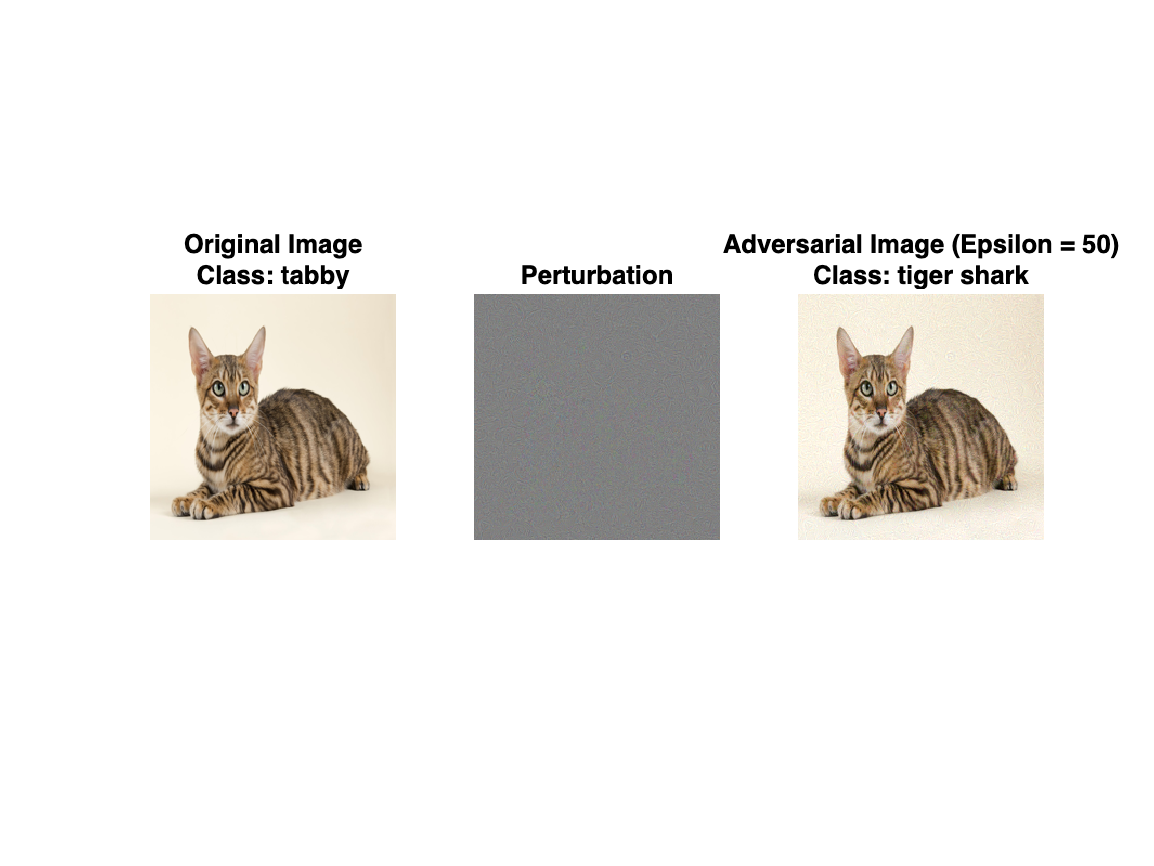

showAdversarialImage(X,YPred,XAdvTarget,YPredAdvTarget,epsilon);

Because of imperceptible perturbation, the network classifies the adversarial image as a tiger shark. 

## Supporting Functions

### Untargeted Input Gradient Function

Calculate the gradient used to create an untargeted adversarial example. This gradient is the gradient of the cross-entropy loss.

function gradient = untargetedGradients(dlnet,X,target)

Y = predict(dlnet,X);
Y = stripdims(squeeze(Y));
loss = crossentropy(Y,target,'DataFormat','CB');
gradient = dlgradient(loss,X);

end

### Targeted Input Gradient Function

Calculate the gradient used to create a targeted adversarial example. This gradient is the gradient of the mean squared error.

function gradient = targetedGradients(dlnet,X,target)

Y = predict(dlnet,X);
Y = stripdims(squeeze(Y));
loss = mse(Y,target,'DataFormat','CB');
gradient = dlgradient(loss,X);

end

### Show Adversarial Image

Show an image, the corresponding adversarial image, and the difference between the two (perturbation).

function showAdversarialImage(image,label,imageAdv,labelAdv,epsilon)

figure
subplot(1,3,1)
imgTrue = uint8(extractdata(image));
imshow(imgTrue)
title("Original Image" + newline + "Class: " + string(label))

subplot(1,3,2)
perturbation = uint8(extractdata(imageAdv-image+127.5));
imshow(perturbation)
title("Perturbation")

subplot(1,3,3)
advImg = uint8(extractdata(imageAdv));
imshow(advImg)
title("Adversarial Image (Epsilon = " + string(epsilon) + ")" + newline + ...
    "Class: " + string(labelAdv))
end

## References

[1] Goodfellow, Ian J., Jonathon Shlens, and Christian Szegedy. “Explaining and Harnessing Adversarial Examples.” Preprint, submitted March 20, 2015. https://arxiv.org/abs/1412.6572.

[2] *ImageNet*. http://www.image-net.org.

[3] Szegedy, Christian, Wojciech Zaremba, Ilya Sutskever, Joan Bruna, Dumitru Erhan, Ian Goodfellow, and Rob Fergus. “Intriguing Properties of Neural Networks.” Preprint, submitted February 19, 2014. https://arxiv.org/abs/1312.6199.

[4] Kurakin, Alexey, Ian Goodfellow, and Samy Bengio. “Adversarial Examples in the Physical World.” Preprint, submitted February 10, 2017. https://arxiv.org/abs/1607.02533.

[5] Madry, Aleksander, Aleksandar Makelov, Ludwig Schmidt, Dimitris Tsipras, and Adrian Vladu. “Towards Deep Learning Models Resistant to Adversarial Attacks.” Preprint, submitted September 4, 2019. https://arxiv.org/abs/1706.06083.

*Copyright 2020 The MathWorks, Inc.*